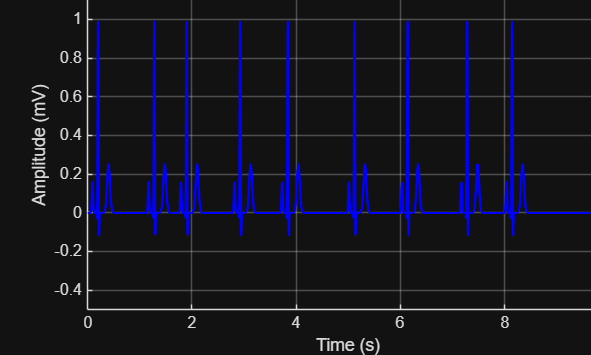

duration = 10;
fs       = 1000;
t        = 0 : 1/fs : duration;
ecg      = zeros(size(t));

% Wave parameters
a = [ 0.25, -0.2,  1.6, -0.4,  0.4];
b = [ 0.09, 0.185, 0.20, 0.215, 0.40];
c = [0.015, 0.008, 0.012, 0.008, 0.04];

% Random beat onsets (irregular spacing)
onsets = cumsum([0,  0.5 + 0.8*rand(1, 8)]);
onsets = onsets(onsets < duration - 0.5);

% Build ECG
for k = onsets
    for i = 1:5
        ecg = ecg + (a(i)/1.6) .* exp(-((t - k - b(i))./c(i)).^2);
    end
end

% Plot
figure;
plot(t, ecg, 'b', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Amplitude (mV)');
title('Arrhythmia ECG'); grid on;
ylim([-0.5, 1.2]);


% ---- Package for Simulink ----
ecg_sim.time               = t';
ecg_sim.signals.values     = ecg';
ecg_sim.signals.dimensions = 1;
